# Distribuciones en una dimensión

Autor: Juan Parras

Asignatura: SALT

## Distribución de Bernoulli

- Distribución discreta

- Rango: $X\in \left\lbrace 0,1\right\rbrace$

- Parámetro: $p\in \left\lbrack 0,1\right\rbrack$ (probabilidad de sacar un 1)

p = 0.38

p = 0.3800

n_muestras = 1000;
muestras = random('Binomial', 1, p, 1, n_muestras); % La Bernoulli se genera a través de la Binomial
muestras(1:10)

ans =      1     1     0     1     0     1     0     0     0     0


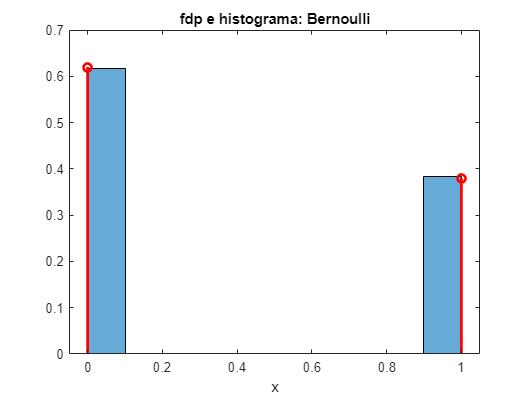


rango = 0:1;
nbins = 10;
histogram(muestras, nbins, 'Normalization', 'probability');
hold on;
stem(rango, pdf('Binomial', rango, 1, p), 'r', 'LineWidth', 2);
hold off;
title('fdp e histograma: Bernoulli')
xlabel('x')

Podemos calcular los estadísticos usando las expresiones vistas en teoría, y comprobar que en la práctica, nos aproximamos

media_teoria = p

media_teoria = 0.3800

media_empirica = mean(muestras)

media_empirica = 0.3840

varianza_teoria = p * (1 - p)

varianza_teoria = 0.2356

varianza_empirica = var(muestras)

varianza_empirica = 0.2368

## Distribución Binomial

- Distribución discreta: es la suma de $n$ Bernoullis independientes

- Rango: $X\in \left\lbrace 0,1,\ldotp \ldotp \ldotp ,n\right\rbrace$

- Parámetro: $p\in \left\lbrack 0,1\right\rbrack$ (probabilidad de sacar un 1), $n\in \mathbb{N}$ (número de experimentos de Bernoulli)

p = 0.24

p = 0.2400

n =15

n = 15

n_muestras = 1000;
muestras = random('Binomial', n, p, 1, n_muestras);
muestras(1:10)

ans =      3     5     5     2     5     2     5     6     0     2


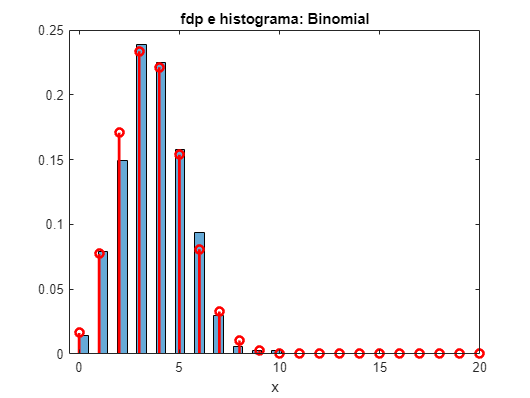


rango = 0:20;
nbins = 21;
histogram(muestras, nbins, 'Normalization', 'probability');
hold on;
stem(rango, pdf('Binomial', rango, n, p), 'r', 'LineWidth', 2);
hold off;
title('fdp e histograma: Binomial')
xlabel('x')

Podemos calcular los estadísticos usando las expresiones vistas en teoría, y comprobar que en la práctica, nos aproximamos

media_teoria = n * p

media_teoria = 3.6000

media_empirica = mean(muestras)

media_empirica = 3.6630

varianza_teoria = n * p * (1 - p)

varianza_teoria = 2.7360

varianza_empirica = var(muestras)

varianza_empirica = 2.7422

## Distribución de Poisson

- Distribución discreta

- Rango: $X\in \left\lbrace 0,1,\ldotp \ldotp \ldotp ,\infty \;\right\rbrace$

- Parámetro: $a>0$

a = 1.7

a = 1.7000

n_muestras = 1000;
muestras = random('Poisson', a, 1, n_muestras);
muestras(1:10)

ans =      3     3     6     0     1     2     2     2     0     0


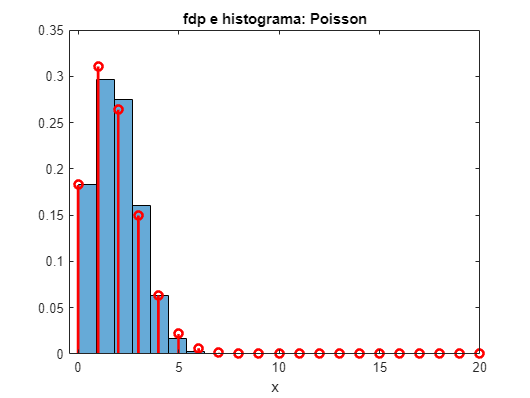


rango = 0:20;
nbins = max(muestras)+1;
histogram(muestras, nbins, 'Normalization', 'probability');
hold on;
stem(rango, pdf('Poisson', rango, a), 'r', 'LineWidth', 2);
hold off;
title('fdp e histograma: Poisson')
xlabel('x')

Podemos calcular los estadísticos usando las expresiones vistas en teoría, y comprobar que en la práctica, nos aproximamos

media_teoria = a

media_teoria = 1.7000

media_empirica = mean(muestras)

media_empirica = 1.6980

varianza_teoria = a

varianza_teoria = 1.7000

varianza_empirica = var(muestras)

varianza_empirica = 1.6264

## Distribución Uniforme

- Distribución continua

- Rango: $X\in \left\lbrack a,b\right\rbrack$

- Parámetros: $a,b\in \mathbb{R}\;$(límite inferior y superior del rango, respectivamente)

a = -8.4

a = -8.4000

b = 11.2

b = 11.2000

n_muestras = 1000;
muestras = random('Uniform', a, b, 1, n_muestras);
muestras(1:10)

ans =     3.7392    7.6646   -3.1526    4.0681   -8.1150   -6.1674    3.5683   -7.0130    6.3256   11.1153


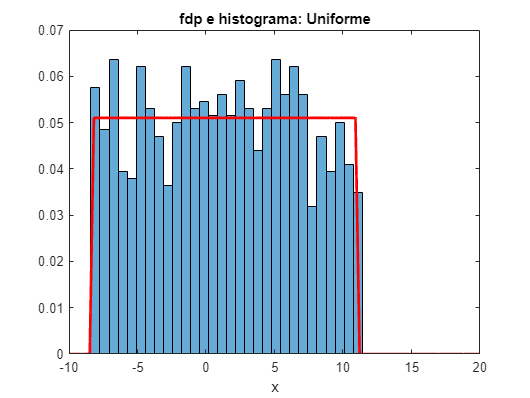


rango = linspace(-10, 20, 100);
nbins = 30;
histogram(muestras, nbins, 'Normalization', 'pdf');
hold on;
plot(rango, pdf('Uniform', rango, a, b), 'r', 'LineWidth', 2);
hold off;
title('fdp e histograma: Uniforme')
xlabel('x')

Podemos calcular los estadísticos usando las expresiones vistas en teoría, y comprobar que en la práctica, nos aproximamos

media_teoria = (b + a ) / 2

media_teoria = 1.4000

media_empirica = mean(muestras)

media_empirica = 1.2721

varianza_teoria = (b - a)^2 / 12

varianza_teoria = 32.0133

varianza_empirica = var(muestras)

varianza_empirica = 30.8798

## Distribución Exponencial

- Distribución continua

- Rango: $X\in \left(0,\infty \;\right)$

- Parámetros: $\lambda \in \left(0,\infty \;\right)$(inverso de la media)

lambda = 2.1

lambda = 2.1000

n_muestras = 1000;
muestras = random('Exponential', 1 / lambda, 1, n_muestras);
muestras(1:10)

ans =     0.2286    0.0386    0.5273    0.1252    1.5963    0.1441    0.9567    0.2987    0.0220    0.1438


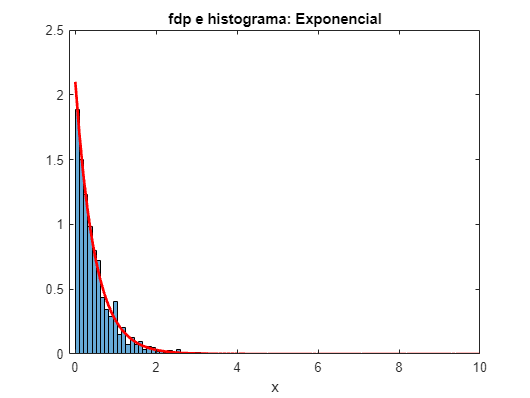


rango = linspace(0, 10, 100);
nbins = 30;
histogram(muestras, nbins, 'Normalization', 'pdf');
hold on;
plot(rango, pdf('Exponential', rango, 1 / lambda), 'r', 'LineWidth', 2);
hold off;
title('fdp e histograma: Exponencial')
xlabel('x')

Podemos calcular los estadísticos usando las expresiones vistas en teoría, y comprobar que en la práctica, nos aproximamos

media_teoria = 1 / lambda

media_teoria = 0.4762

media_empirica = mean(muestras)

media_empirica = 0.4763

varianza_teoria = 1 / lambda^2

varianza_teoria = 0.2268

varianza_empirica = var(muestras)

varianza_empirica = 0.2278

## Distribución Gaussiana o Normal

- Distribución continua

- Rango: $X\in \left(-\infty \;,\infty \;\right)$

- Parámetros: $\eta \in \mathbb{R}\;$(media), $\sigma \in \left(0,\infty \;\right)$ (desviación típica)

eta = 3

eta = 3

sigma = 1.5

sigma = 1.5000

n_muestras = 1000;
muestras = random('Normal', eta, sigma, 1, n_muestras);
muestras(1:10)

ans =     2.1476   -0.7380    2.7206    3.1063    3.7962    3.2244    4.0807    3.2888    0.7848    4.0287


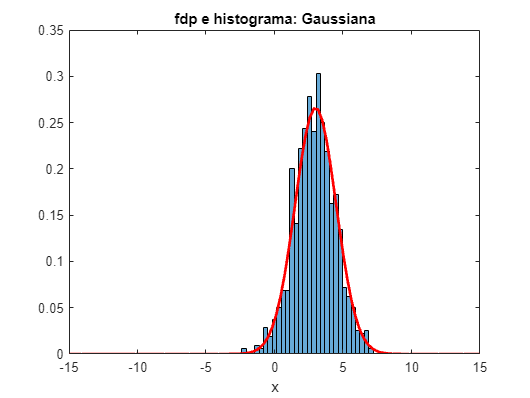


rango = linspace(-15, 15, 100);
nbins = 30;
histogram(muestras, nbins, 'Normalization', 'pdf');
hold on;
plot(rango, pdf('Normal', rango, eta, sigma), 'r', 'LineWidth', 2);
hold off;
title('fdp e histograma: Gaussiana')
xlabel('x')

Podemos calcular los estadísticos usando las expresiones vistas en teoría, y comprobar que en la práctica, nos aproximamos

media_teoria = eta

media_teoria = 3

media_empirica = mean(muestras)

media_empirica = 2.9478

varianza_teoria = sigma^2

varianza_teoria = 2.2500

varianza_empirica = var(muestras)

varianza_empirica = 2.2366